clear all
clc
clf
load('./rawSample/exp2/l_6_2.mat')

WIFI_SN = WIFI_SN(1:numDetectedPackets);
WIFI_CRC = WIFI_CRC(1:numDetectedPackets);
SSIC_SN = SSIC_SN(1:numDetectedPackets);
SSIC_header_CRC = SSIC_header_CRC(1:numDetectedPackets);
SSIC_layload_CRC = SSIC_layload_CRC(1:numDetectedPackets);

length(WIFI_SN(WIFI_SN  ==-1))

ans = 236

length(SSIC_SN(SSIC_SN  ==-1))

ans = 67

length(WIFI_CRC(WIFI_CRC ==-1))

ans = 236

length(SSIC_header_CRC(SSIC_header_CRC ==-1))

ans = 67

length(SSIC_layload_CRC(SSIC_layload_CRC==-1))

ans = 194

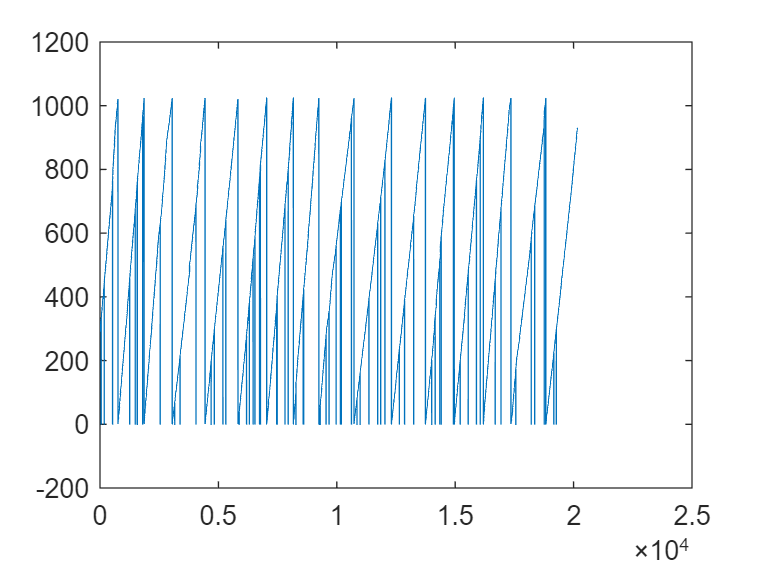


plot(SSIC_SN)


round_start_index = find(SSIC_SN==1)'

round_start_index =         3049        3050        4437        4438        5827        5828        7040        7041        8166        8167        9243        9244       10727       10728       12308       12309       13743       13744       14961       14962       16190       16191       17353       17354       18829       18830



%l_1_1
% round_start_index = [1055;2543;3916;5221;6495;8138;9641;11043;12299;13481;14718];
%l_1_2
% round_start_index = [10442;12042;13502;14846;16190;17815;19345;20739;22019;23275;24935;26462];

%l_2_1
% round_start_index = [798;2023;3210;4542;6268;7829;9255;10641;11917;13566 ;15065;17643;18863];
%l_2_2
% round_start_index = [991;2451;3822;5102;6797;8372;9788;11135;12376;13585;15277];

%l_3_1
% round_start_index = [76;1352;3040;4647;6112;7450;8718;10080;11695;13129;14479];
%l_3_2
% round_start_index = [1315;2606;3846;5018;6132;7611;8946;10198;11413;13004;14496];

%l_4_1
% round_start_index = [615;1888;3102;4118;5178 ;7509;9059;10451;11665;12798;13850];
%l_4_2
% round_start_index = [659;1911;3098;4211;5194;6154;7063;8000;9600;10983;12255];

%l_5_1
% round_start_index = [908;2132;3307;4821;6340;7751;9039;10271;11656;13182;14580];
%l_5_2
% round_start_index = [1147;2387;3882;5489;6940;8284;9681;11380;12888;14266;15573];

%l_6_1
% round_start_index = [306;1684;2927;4059;5166;6484;7909;9212;10465;11587;12760];
%l_6_2
round_start_index = [1863;3049;4437;5827;7040;8166;9243;10727;12308;13743;14961];

%l_7_1
% round_start_index = [];
%l_7_2
% round_start_index = [];

%l_8_1
% round_start_index = [];
%l_8s_2
% round_start_index = [];

% round_start_index = [333;1405;2470;3494;5102;6624;7914;9027;10184;11200;12672;14012;15313;16494;18584];
% round_start_index = [333;1405;2470;3494;5102;6624;7914;9027];
% round_start_index = [391;1567;2766;3865;4831;6297;7749;8906;10204;10929;12081;13644]
% round_start_index = [7749;8906;10204;10929;12081;13644
% round_start_index = [555;1882;3122;4244;5252;6247;7661;8929;10152;11320;12343;13358;14352;15837]
% round_start_index = [7661;8929;10152;11320;12343;13358;14352;15837]
% round_start_index = [round_start_index(1:8);8682;round_start_index(9)] %ch1_SSIC_1M_CRC_1
% round_start_index = [round_start_index(1:12);13033;round_start_index(9)] %ch1_SSIC_4M_CRC_1_NLOS
% round_start_index = [round_start_index(1:12);12429;round_start_index(13:18);19492;round_start_index(19:end)] %1m_2
% round_start_index = [round_start_index(1:12);12343;round_start_index(13:19)] %2m_2
% round_start_index = [round_start_index(1:7);7082;round_start_index(8:10)]
% round_start_index = [round_start_index(1:5);5324;round_start_index(6:10)]
% round_start_index = [round_start_index(1);1598;round_start_index(2:9)]
% round_start_index = round_start_index(1:11)
% round_start_index = [round_start_index(1:16);16202;round_start_index(17:end)]


global_rounds = length(round_start_index) -1;
packet_per_round = 1024;

sorted_CONV_LLR_Collection = zeros(size(CONV_LLR_Collection));
sorted_SSIC_LLR_Collection = zeros(size(SSIC_LLR_Collection));
packet_status = ones(global_rounds*packet_per_round,1)*-1; 
% 2: header valid, payload valid 
% 1: header valid, payload invalid
% 0: header invalid, payload invalid
% -1: loss
cur_SSIC_SN = 0;
for round_index = 1:global_rounds

    data_range = round_start_index(round_index):round_start_index(round_index+1)-1;

    for tmp = 1:length(data_range)
        data_index = data_range(tmp);

        % check VC header
        if SSIC_header_CRC(data_index) == 1  
            pre_cur_SSIC_SN = cur_SSIC_SN;
            cur_SSIC_SN = SSIC_SN(data_index);

            if cur_SSIC_SN == pre_cur_SSIC_SN 
                % this is a retransmission, which is not in the
                % consideration
                continue
            end


            % Header is vaild, stort LLRs
            store_index = cur_SSIC_SN + (round_index-1)*1024;

            sorted_CONV_LLR_Collection(store_index,:) = CONV_LLR_Collection(data_index,:);
            sorted_SSIC_LLR_Collection(store_index,:) = SSIC_LLR_Collection(data_index,:);
            
            if WIFI_CRC(data_index) == 1
            % 2: header valid, payload valid
                packet_status(store_index) = 2;
            else
            % 1: header valid, payload invalid
                packet_status(store_index) = 1;
            end
        else
            % 0: header invalid, payload invalid
            packet_status(store_index) = 0;
        end
    end
end

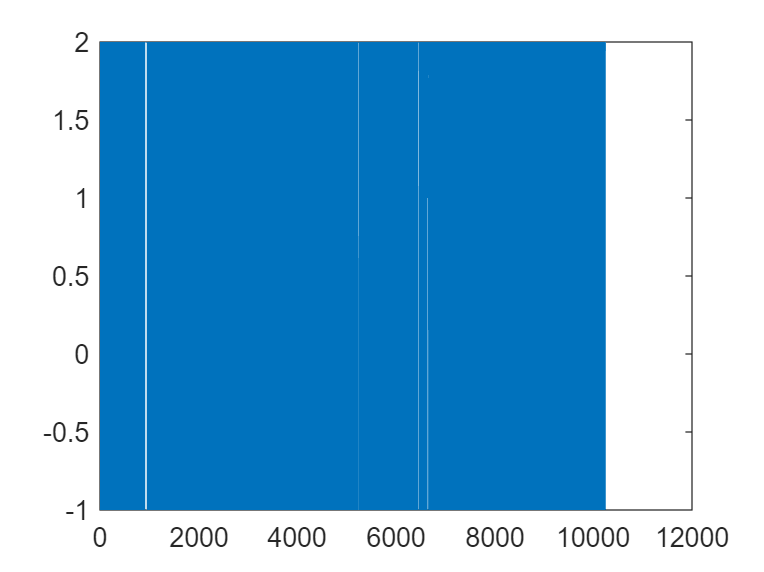

clf
plot(packet_status)


final_numdetectedPackets  = length(packet_status(packet_status~=-1));
final_numlossPackets      = length(packet_status(packet_status==-1));
PLR                       = final_numlossPackets/(final_numdetectedPackets+final_numlossPackets);

final_numValidPackets   = length(packet_status(packet_status==2));
final_numinValidPackets = length(packet_status(packet_status==1))+ length(packet_status(packet_status==0));
PER                     = final_numinValidPackets/(final_numinValidPackets+final_numValidPackets);

final_numValidHeaders   = length(packet_status(packet_status==2)) + length(packet_status(packet_status==1));
final_numinValidHeaders = length(packet_status(packet_status==0));
HER                     = final_numinValidHeaders/(final_numValidHeaders+final_numinValidHeaders);

disp([num2str(final_numdetectedPackets), ' Packets Detected'])

6718 Packets Detected


disp([num2str(final_numlossPackets),   ' Packets Loss'])

3522 Packets Loss


disp(['Packet Loss Rate (PLR)',num2str(PLR) ])

Packet Loss Rate (PLR)0.34395



disp([num2str(final_numValidPackets), ' Packets Valid'])

6624 Packets Valid


disp([num2str(final_numinValidPackets),   ' Packets inValid'])

94 Packets inValid


disp(['Packet Error Rate (PER)',num2str(PER) ])

Packet Error Rate (PER)0.013992



disp([num2str(final_numValidHeaders), ' Headers Valid'])

6673 Headers Valid


disp([num2str(final_numinValidHeaders),   ' Headers inValid'])

45 Headers inValid


disp(['Header Error Rate (PER)',num2str(HER) ])

Header Error Rate (PER)0.0066984


save('./rawSample/exp2/l_6_2_post.mat'...
    ,'sorted_CONV_LLR_Collection','sorted_SSIC_LLR_Collection','packet_status'...
    ,'PLR','PER','HER')